## USE "Run Section"

## Let's simulate an acquisition equipment.

% Load data.
% This dataset represents the output of the acquisition equipment.

addpath('data')
load('DatasetENEEB.mat')

% What we know about the data:
sampling_freq=4;

% You should see TRAIN, TEST1, TEST2 and chans_label 
% in MATLAB's Workspace.

## Let's see what is inside each variable.

traindata is a 41x1280

[train_rows, train_cols]=size(TRAIN);
[num_chans]=numel(chans_labels);

fprintf('Our training set has %i samples, and %i channels.\n', train_cols, num_chans);

Our training set has 1280 samples, and 40 channels.


## Checking the training data.

First we have to select a channel.

chan_idx=1;

Now we can plot it over time.

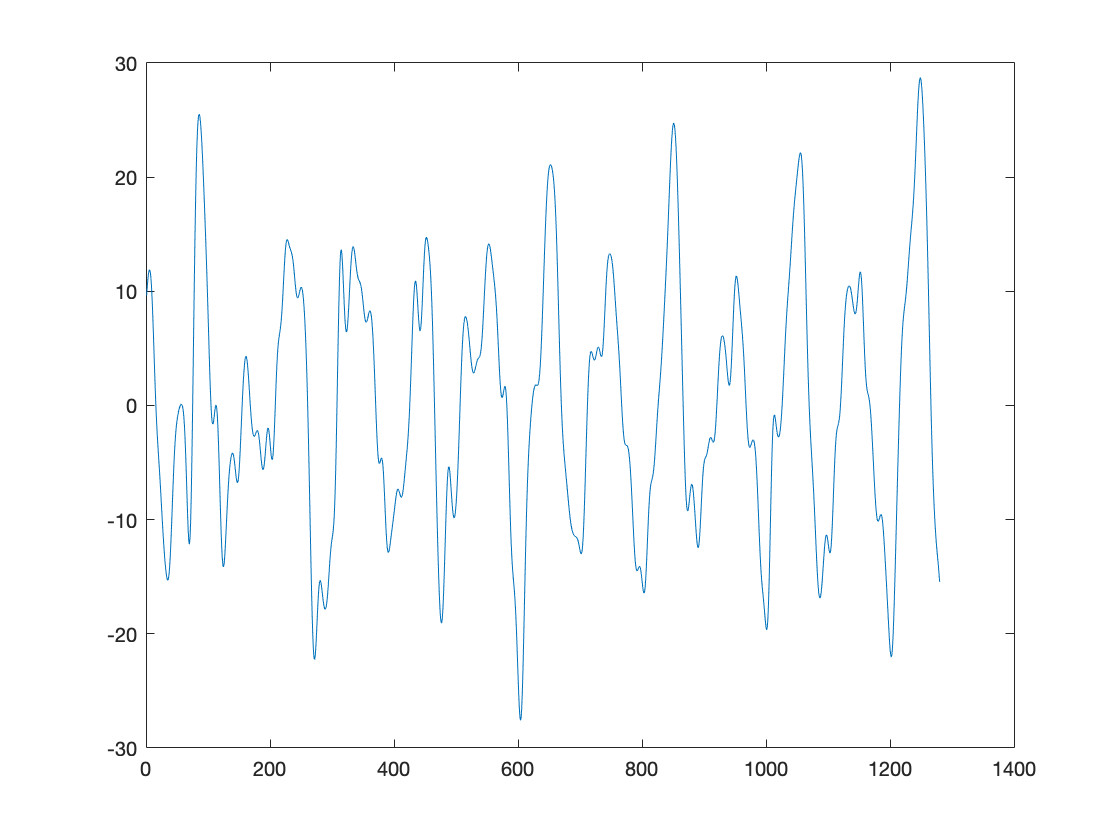

figure, 
plot(TRAIN(chan_idx,:))

Re-arrange the plot considering what we know.

Sampling_Freq=4Hz.

If possible , make a "prettier" plot.

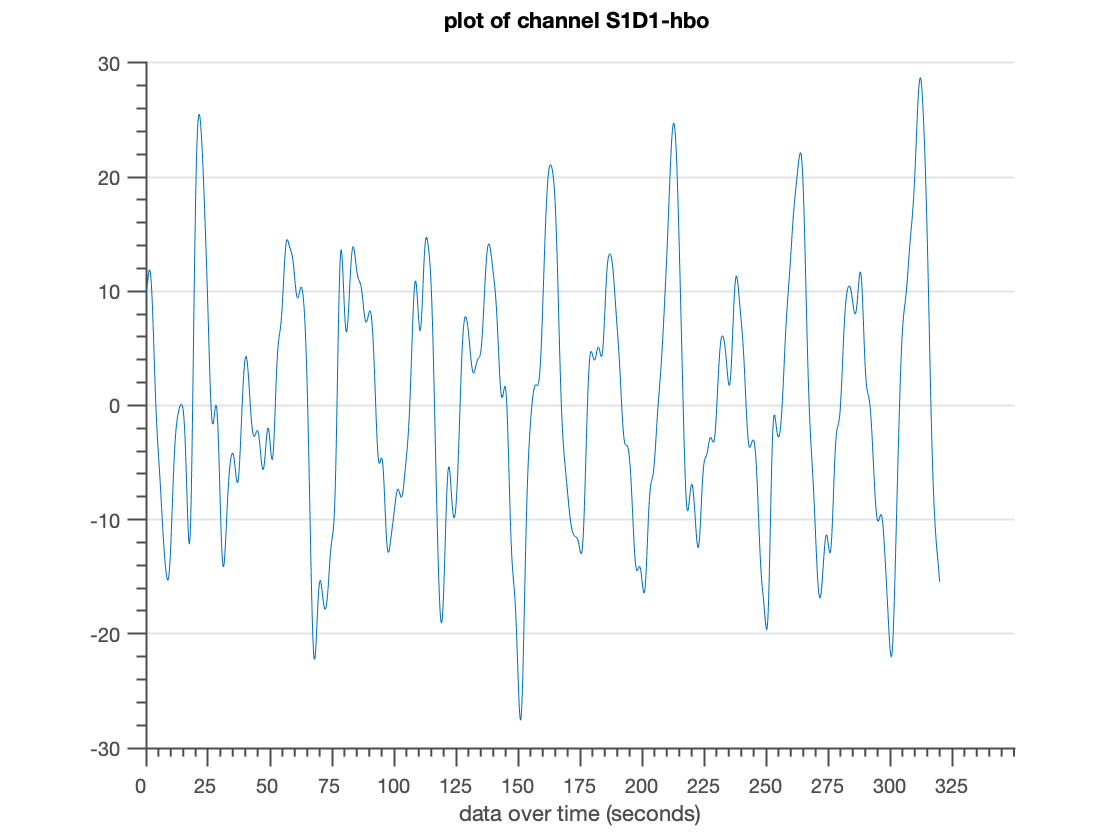

int_t=100;
set(gca, ...
  'Box'         , 'off'     , ...
  'TickDir'     , 'out'     , ...
  'TickLength'  , [.02 .02] , ...
  'XMinorTick'  , 'on'      , ...
  'YMinorTick'  , 'on'      , ...
  'YGrid'       , 'on'      , ...
  'XColor'      , [.3 .3 .3], ...
  'YColor'      , [.3 .3 .3], ...
  'XTick'       , 0:int_t:train_cols+int_t, ...
  'XTickLabel'  , 0:int_t/sampling_freq:(train_cols+int_t)/sampling_freq, ...
  'LineWidth'   , 1         );

ylim=get(gca, 'ylim');

xlabel('data over time (seconds)')

title(sprintf('plot of channel %s \n', chans_labels{chan_idx}))

If you look closely, the matrix TRAIN has 41 lines. The last one represents the task.

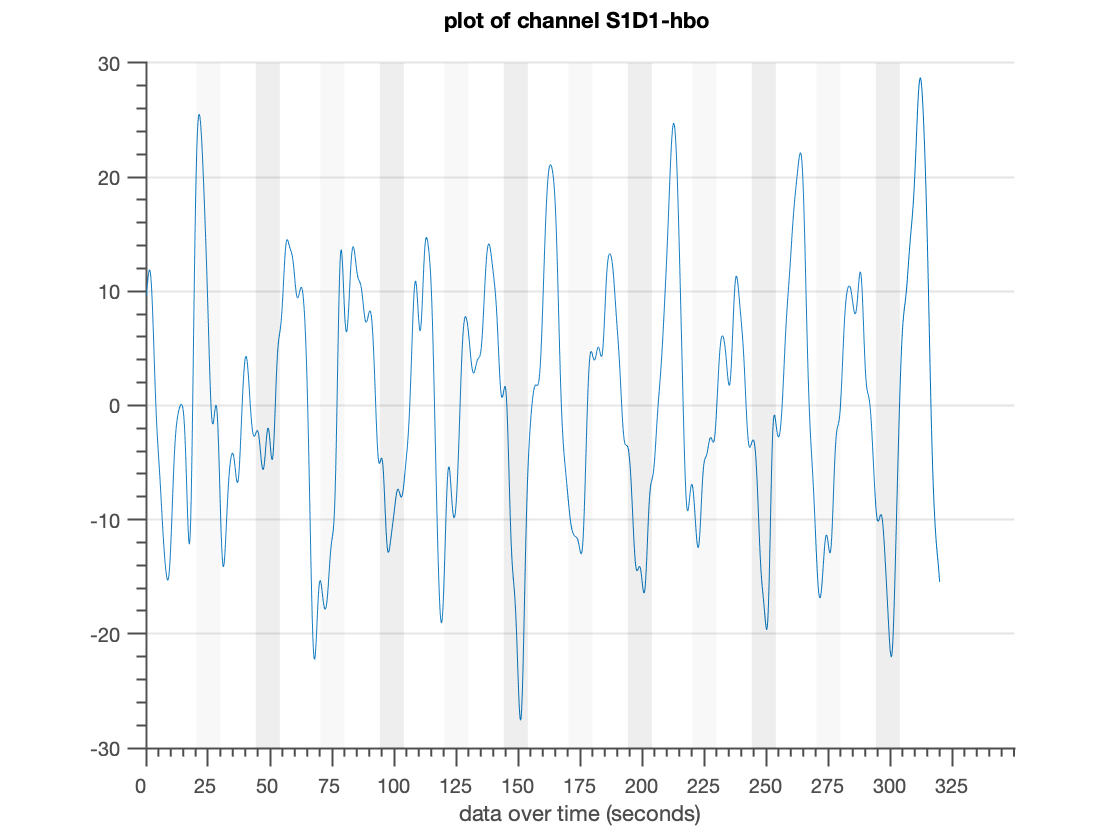

hold on;

idxs=find(diff(TRAIN(end,:)));
st_int=1;
colors=[255, 255, 255;
    190, 190, 190;
    90, 90, 90]/255;

for i=1:numel(idxs)
    end_int=idxs(i);
    
    p=patch([st_int end_int end_int st_int],...
        [ylim(1) ylim(1)  ylim(2) ylim(2)],...
        colors(TRAIN(end,st_int)+1,:));
    set(p, 'FaceAlpha', 0.1,...
           'EdgeColor', 'none')   
    st_int=end_int+1;
end